% Clear
clear all
close all 
clc

% Opening the sent and received files from the USRP.
load("tx_hardware.mat");

rx_f = fopen("rx.dat", 'rb');
tmp_rx = fread(rx_f, 'float32');
fclose(rx_f);

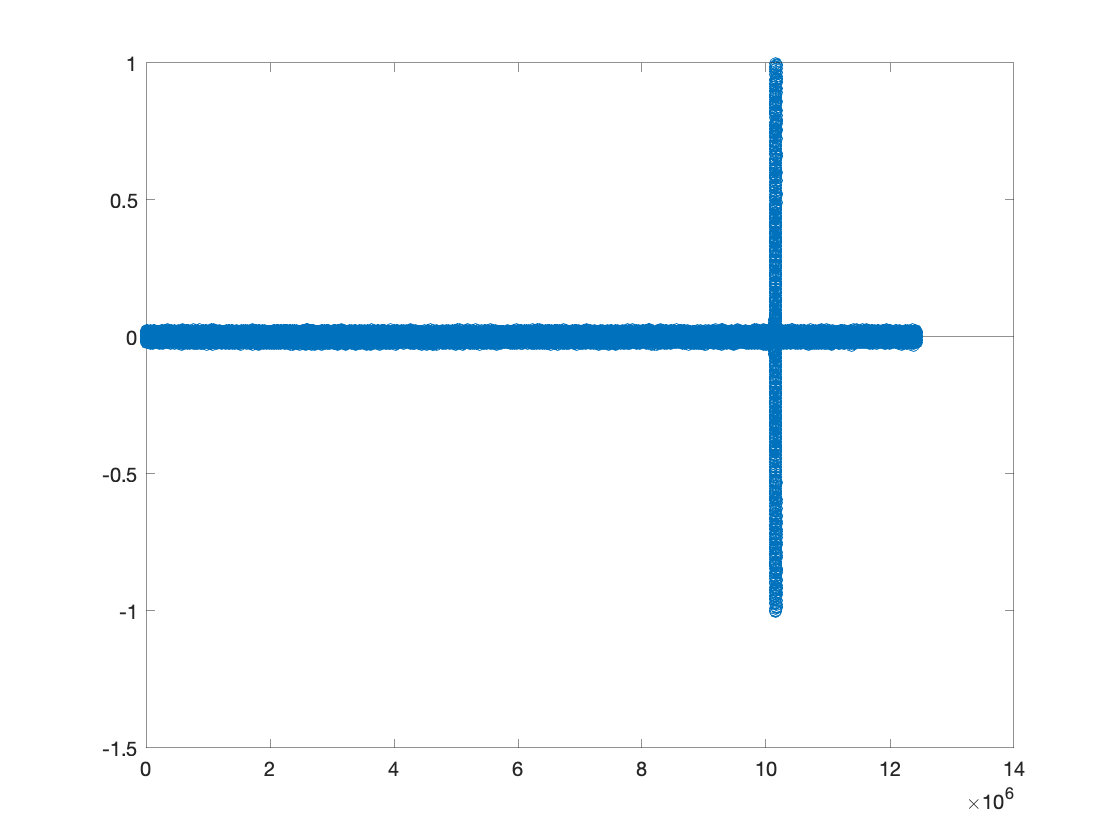

% Interleaving the data into complex numbers.
rx_unprocessed = (tmp_rx(1:2:end)+1j*tmp_rx(2:2:end));
figure
stem(rx_unprocessed);

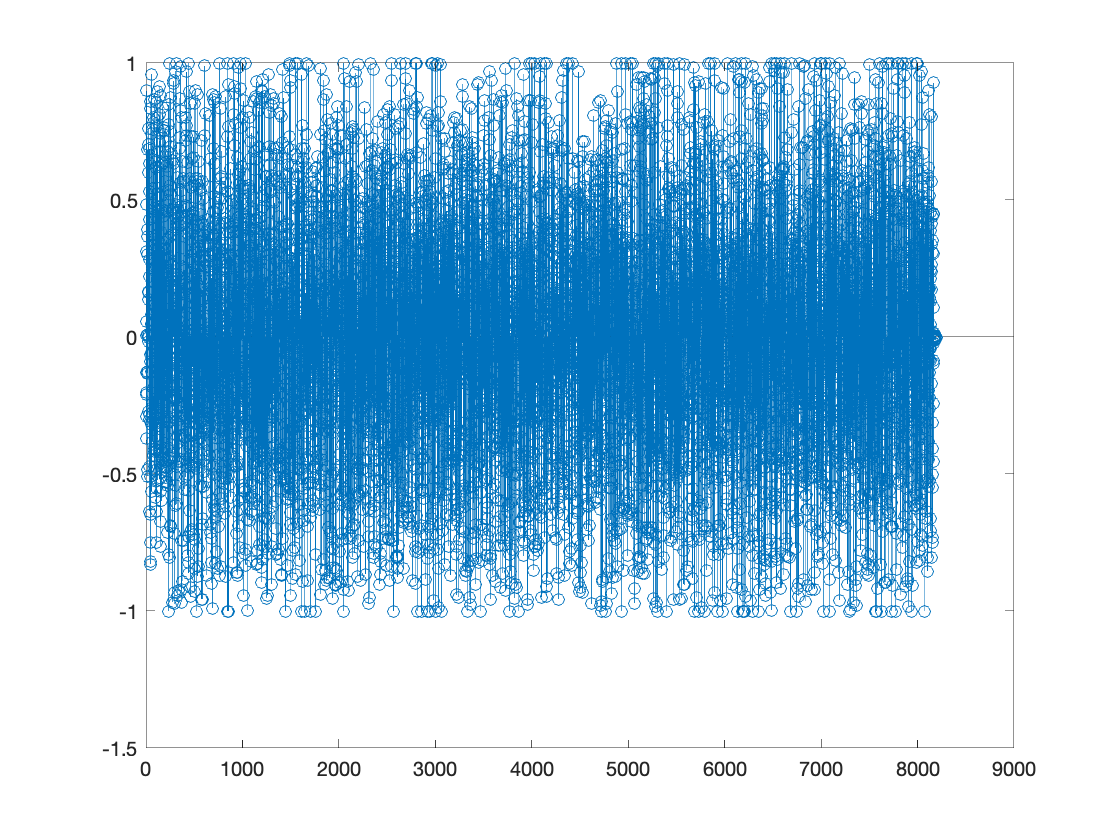

%% Accounting for the delay.
%{
    This delay will remove any unnecessary bits before the start of the
    signal. The final length may not be the same length as what was
    originally sent because the receiver doesn't stop immediately after the
    signal stops.
%}
zero_preamble = [preamble tx(1:end-500)];
[corr,lags] = xcorr(rx_unprocessed, preamble);
[~, Index] = max(abs(corr));
delay = lags(Index);

rx_delay = rx_unprocessed(delay:delay+(block_num * 80)+length(preamble)).'; 
figure
stem(rx_delay)

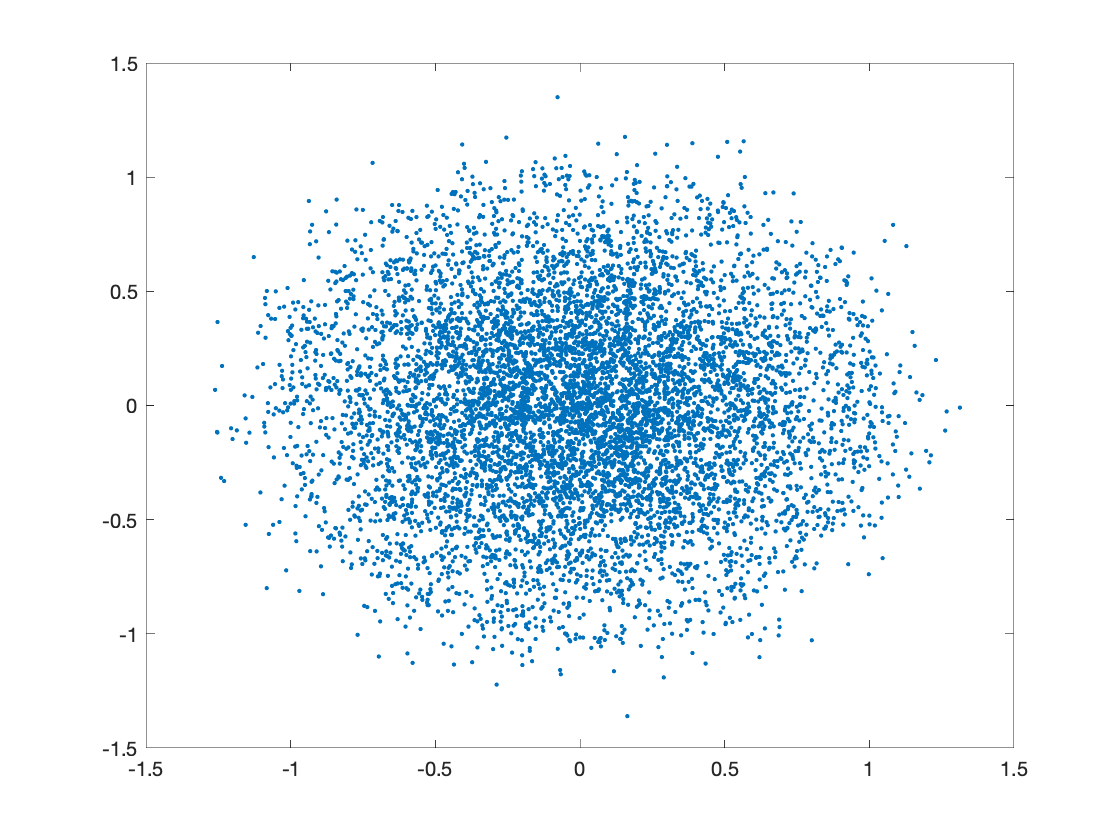

%% Adjusting for the fdelta.
%{
    The second half of the Schmidl Cox algorithm is implemented here. The
    frequency shift can be accounted for here by finding the different
    between the sent prefix and the received prefix.
%}
% Seperating the first and second blocks out.
preamble_len = 3 * block_len; % 1x192
actual_signal_start = preamble_len + 1; % should be 193

% Seperating the preamble from the actual data.
rx_preamble_only = rx_delay(1:preamble_len); % 1x192

signal_length = (block_len + prefix_len) * block_num;
actual_signal_end = signal_length + preamble_len;
rx_without_preamble = rx_delay(actual_signal_start : actual_signal_end);

first_lts_start = block_len + 1; % should be 65
first_lts_end = (block_len * 2); % should be 128
second_lts_start = first_lts_end + 1; % should be 129
second_lts_end = (block_len * 3); % should be 192

first_lts = rx_preamble_only(first_lts_start : first_lts_end); % 1x64
second_lts = rx_preamble_only(second_lts_start : second_lts_end); % 1x64

% Calculating F_delta.
f_sum = 0;
divided = angle(second_lts ./ first_lts); % 1x64
f_sum = sum(divided);
f_delta = f_sum / 64 / 64;

% Apply F_delta.
indices = [1:length(rx_without_preamble)];
exponents = exp(-1 * 1j * f_delta * indices);
rx_freq_adjusted = rx_without_preamble .* exponents;

figure
plot(rx_freq_adjusted, '.')

% Removing the cyclic prefix and converting to the frequency domain.
%{
    For each block, the prefix is removed and the DFT is taken.
    The final length of the signal will be the total block number
    multiplied by 64. The final length will be 6400 as there are 100
    blocks.
%}
% the length is correct here
rx_cropped = crop_long(rx_freq_adjusted, block_len, prefix_len, block_num);

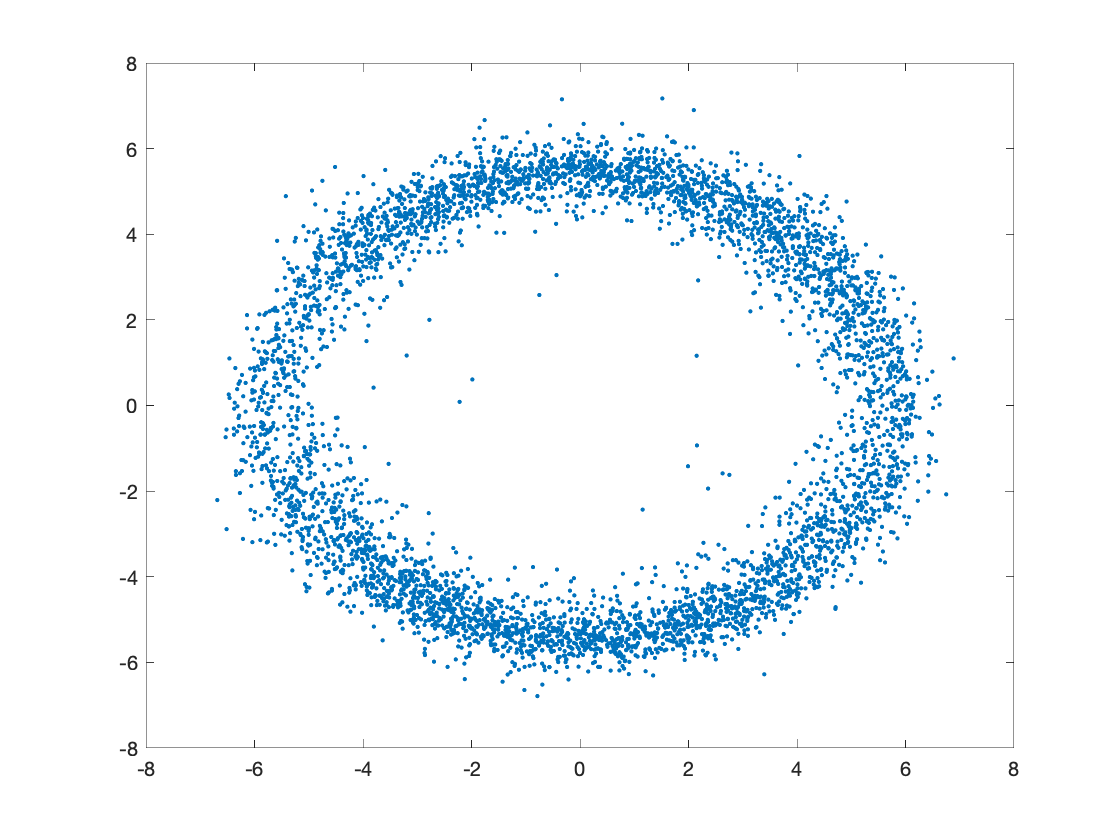

% Remove the guard bands and pilot tones from the data.
rx_no_guard = [];
stop_point = (block_num * block_len) - (block_len - 1);
for i = 1 : block_len : stop_point
    curr_block = rx_cropped(i:(i+block_len - 1));
    no_guard_block = [curr_block(7:32) curr_block(34:59)];
    rx_no_guard = [rx_no_guard no_guard_block];
end
figure
plot(rx_no_guard, '.');

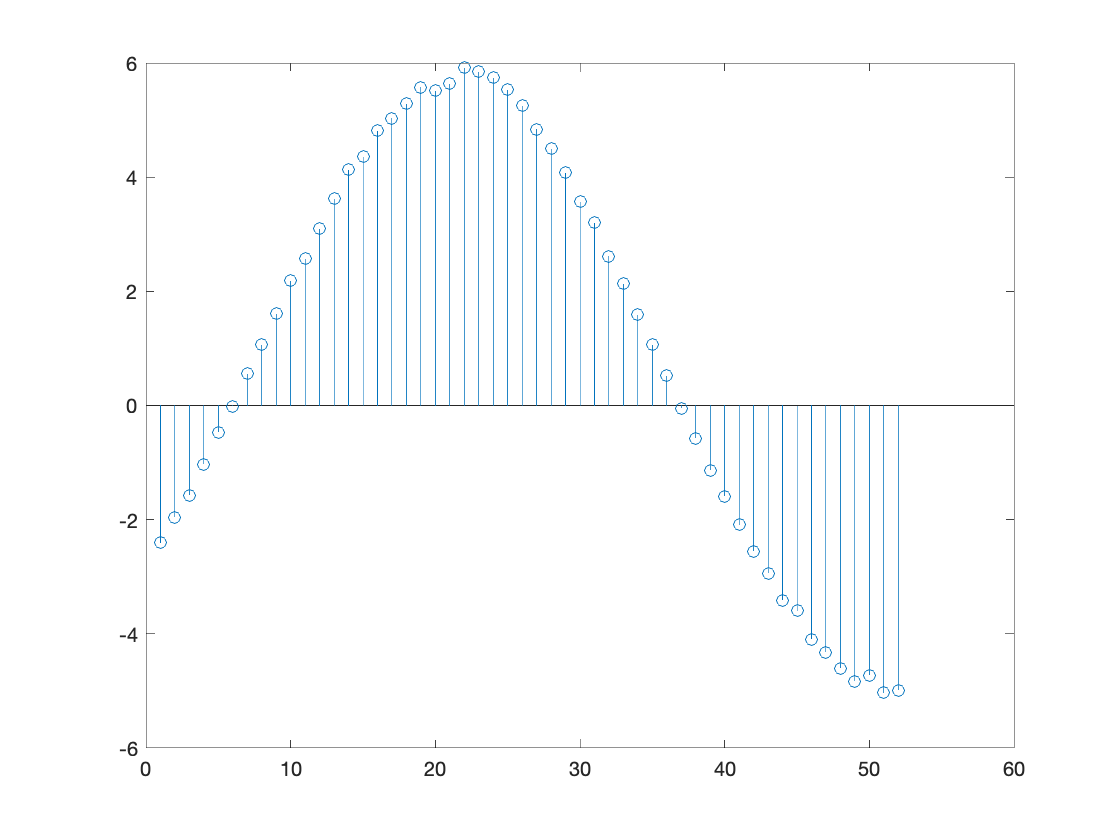

% Channel estimation
multiple_channel_estimations = rx_no_guard(1:832)./tx_channel_no_guard(1:832);
h_stacked = reshape(multiple_channel_estimations, [no_guards_len, block_channel]).';
H = mean(h_stacked);
figure
stem(H)

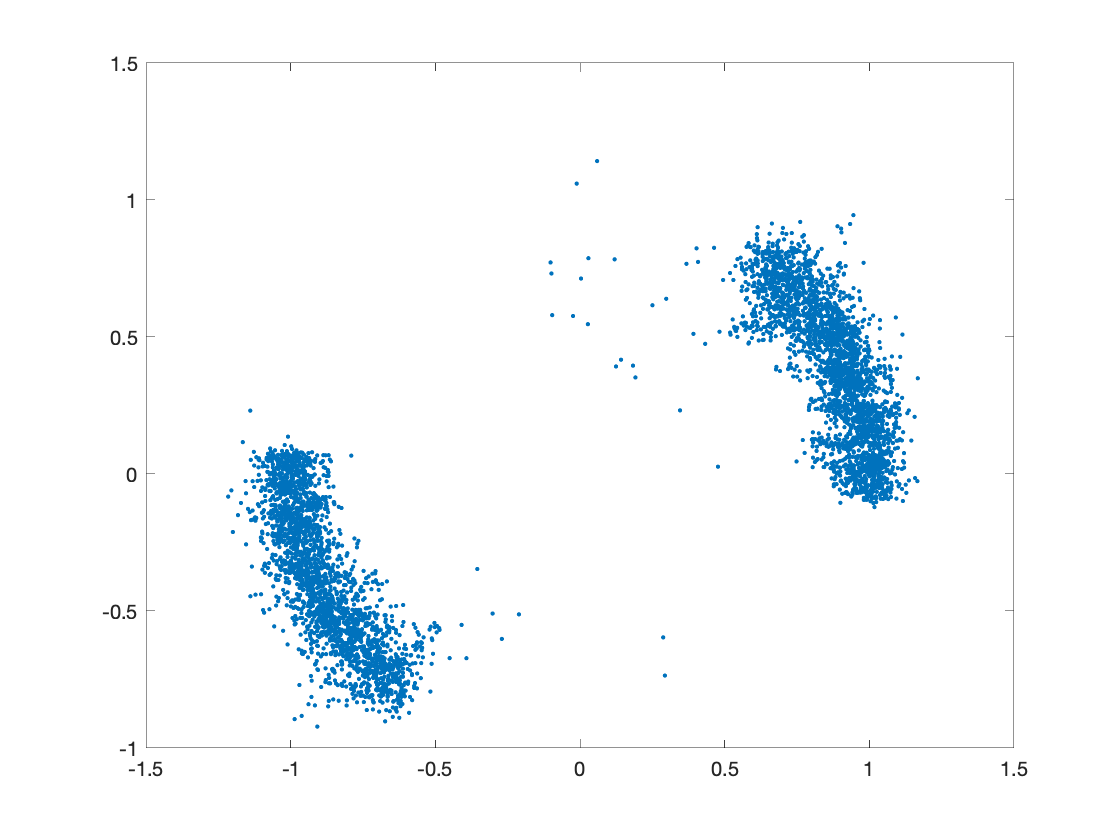


repeated_channel = repmat(H,[1, block_num]);
rx_channel_corrected = rx_no_guard./repeated_channel;
figure
plot(rx_channel_corrected,'.');

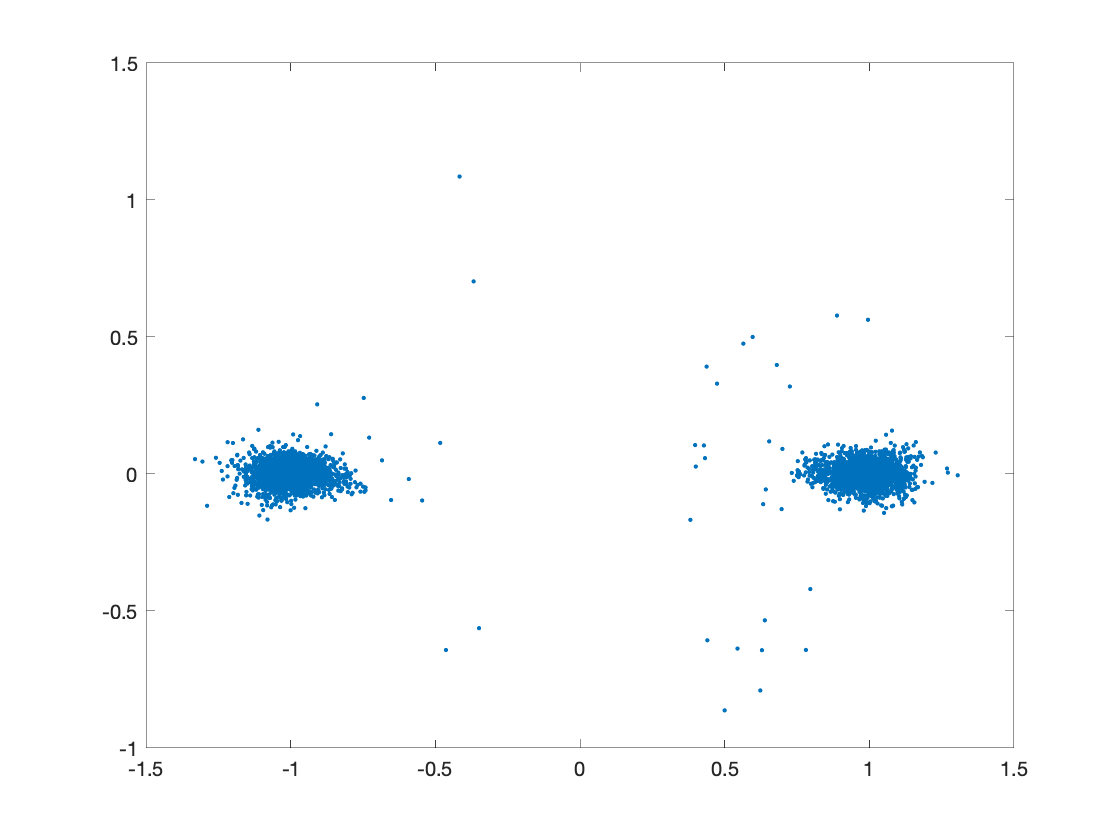

% Correcting for phase offsets using the pilot tones.
rx_phase = [];
stop_point = (block_num * no_guards_len) - (no_guards_len - 1);
for i = 1 : no_guards_len : stop_point
    block_rx = rx_channel_corrected(i:(i+no_guards_len - 1));
    block_tx = tx_channel_no_guard(i:(i+no_guards_len - 1));
    block_no_pilot = [block_rx(1:6) block_rx(8:19) block_rx(21:32) block_rx(34:45) block_rx(47:end)];
    theta1 = angle(block_rx(1,7) / block_tx(1,7));
    theta2 = angle(block_rx(1,20) / block_tx(1,20));
    theta3 = angle(block_rx(1,33) / block_tx(1,33));
    theta4 = angle(block_rx(1,46) / block_tx(1,46));
    theta = mean([theta1, theta2, theta3, theta4]);
    block_phase = block_no_pilot .* exp(-1i*theta);
    rx_phase = [rx_phase block_phase];
    
end
figure
plot(rx_phase, '.');

% Error
X_hat = sign(real(rx_phase));

error = compute_error(X_hat, tx)

error = 0